# **InverseEllipticNome**

Inverse elliptic nome

## Definition


$$q^{-1} \left(q\left(m\right)\right)=m$$



$${\mathit{\mathbf{q}}}^{-1} \left(\mathit{\mathbf{q}}\left(k\right)\right)=k$$


where *k *is the modulus and *m *is the parameter, $q\left(m\right)$ is elliptic nome function. 

Domain:$-1\le q\le 1$.  For the specified domain, the  codomain is the set of real numbers.

Basic features:

Special values:

$q^{-1} \left(-1\right)=-\infty$,  $q^{-1} \left(0\right)=0$,    $q^{-1} \left(1\right)=1$

Identities:

## Syntax

K = InverseEllipticNome(Q)

K = EllipticModulus(Q)

k = ielnome(q)

M = mInverseEllipticNome(Q)

m = mielnome(q)

## Description

**K = InverseEllipticNome(Q)** returns  the modulus K for each element of the array Q (nome). Q must be real array or scalar. **InverseEllipticNome** is the wrapper function which calls the functions **ielnome** element-wise via the function **ufun1**.

**K = EllipticModulus(Q)** returns  the modulus K for each element of the array Q (nome). Q must be real array or scalar. **EllipticModulus** is the wrapper function which calls the functions **ielnome** element-wise via the function **ufun1**.

**k = ielnome(q)** returns  the modulus k for the nome q. It is assumed that  q is  real scalar. y is NaN if q is invalid or convergence failed. **ielnome** is the wrapper function which calls the functions **mielnome**.

**M = mInverseEllipticNome(Q) **returns the parameter M for each element of the array Q (nome). Q must be real array or scalar. **mInverseEllipticNome** is the wrapper function which calls the function **mielnome** element-wise via the function **ufun1**.

**m = mielnome(q) **returns the parameter m  for  the nome q. It is assumed that  q is real scalars without check. y is NaN if  q is invalid or convergence failed.   **mielnome** calculte  m  using the numerical solution of $q\left(m\right)-q=0$.

## Precision

## **Numerical Examples**

**Scalar input**

format long
q = 0.5; 
[ielnome(q)^2, InverseEllipticNome(q)^2, mielnome(q), mInverseEllipticNome(q)]

ans =    0.999989522137310   0.999989522137310   0.999989522137310   0.999989522137310


Accuracy

fprintf('%.16g\n',ielnome(0.5))

0.9999947610549319


% Maple 0.9999947610549319_22

fprintf('%.16g\n',mielnome( -0.09927369733882489))

-3.936187745225642


% Maple  -4

m=0.5;
disp(mielnome(melnome(m)))

   0.500000000000000



**Vector input**

**Matrix input**

## **Graphs **

**Example 1**

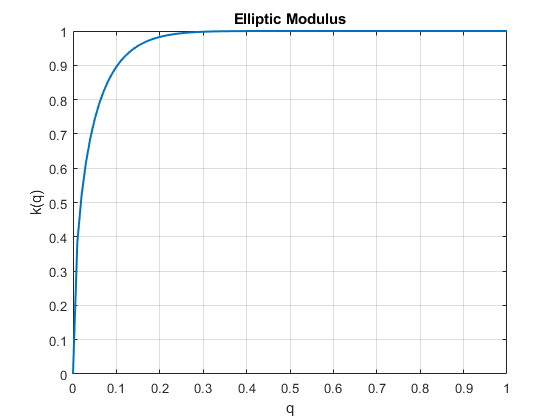

figure
q=0:0.01:1;
plot(q,InverseEllipticNome(q),'LineWidth',1.5)
xlabel('q')
ylabel('k(q)')
title('Elliptic Modulus')
grid on

**Example 2**

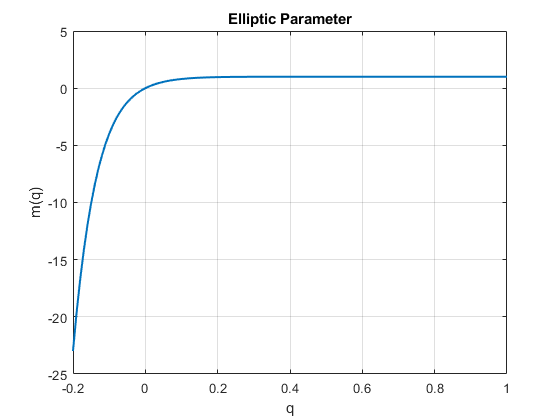

figure
q=-0.2:0.01:1;
plot(q,mInverseEllipticNome(q),'LineWidth',1.5)
xlabel('q')
ylabel('m(q)')
title('Elliptic Parameter')
grid on

**Example 3**

[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticnome.html)

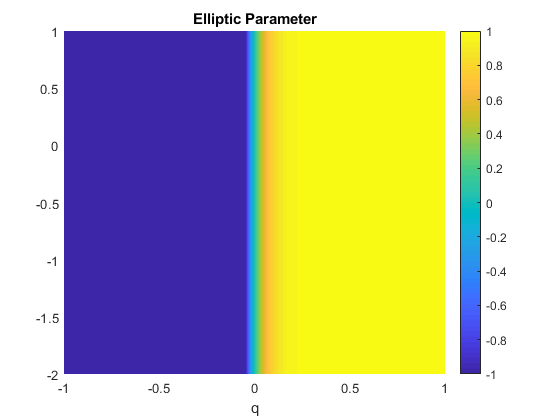

figure
f = @(m)mInverseEllipticNome(m);
fcontour(f,[-1 1 -2 1],'Fill','on','LevelList',-1:0.02:1,'MeshDensity',200)
title('Elliptic Parameter')
xlabel('q')
colorbar
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22.2)

## **References**

## See Also